# Model-Based Demo

Author: Artyom Voronin

Brno 2021

clc; clear all; close all; addpath("../utils/");
addpath("featuretables/"); addpath("functions/");

## Model Based approach using the Hammerstein-Wiener model

This approach use measured data to fit the Hammerstein-Wiener model. The model coefficients are used as features to develop a classification model.

### Import smaller dataensemble

path2data = fullfile('../data/data11/*.mat'); ext_files = ".mat";
datastore = fileEnsembleDatastore(path2data,ext_files);
datastore.ReadFcn = @readData;
datastore.WriteToMemberFcn = @writeData;
datastore.DataVariables = ["LeverPosition"; ...
                            "outValveHP"; ...
                            "outValveWP"];
datastore.ConditionVariables = ["Label"];
datastore.SelectedVariables = ["Label"; ...
                                "LeverPosition"; ...
                                "outValveHP"; ...
                                "outValveWP"];
clear path2data ext_files

### Extract signals

member = read(datastore);
u1 = member.outValveHP{1,1};
u2 = member.outValveWP{1,1};
u = u2.Data - u1.Data;
Ts = 1e-3;

calculate_features = 0;
if calculate_features
opt = oeOptions('Focus','simulation');
B_features = [];
F_features = [];
DC_features = [];
lab_features = [];

reset(datastore)
while hasdata(datastore)
    member = read(datastore);
    label = member.Label;
    x = member.LeverPosition{1,1}.Data;
    data = iddata(x, u, Ts);
    LinearModel = oe(data,[3 2 2],opt);
    mdl = nlhw(data, LinearModel, 'unitgain', 'saturation');
    B_features = [B_features; mdl.B{1,1}(3:end)];
    F_features = [F_features; mdl.F{1,1}];
    DC_features = [DC_features; dcgain(mdl)];
    lab_features = [lab_features; label]; 
    disp(string(progress(datastore)*100) + "% Done");
end
features_table = table(lab_features,DC_features,B_features(:,1),B_features(:,2),B_features(:,3),F_features(:,1),F_features(:,2),F_features(:,3), 'VariableNames', ["Label", "f1","f2","f3","f4","f5","f6","f7"])
else
    feature_table = load("features_table.mat").features_table
end

feature_table = 660×8 table
     Label        f1           f2            f3            f4        f5       f6          f7   
    ________    _______    __________    __________    __________    __    ________    ________

    "health"    0.30575      0.037273     -0.046688     0.0099372    1     -0.48497    -0.51333
    "health"    0.34656      0.054551    -0.0053757     -0.048624    1     -0.10396    -0.89445
    "health"      -1371      0.014093     -0.028052      0.013958    1       -1.999     0.99901
    "valve1"    0.35924      0.090554      -0.18022      0.089671    1      -1.9911     0.99111
    "valve1"     0.5059        0.1528      -0.30537       0.15258    1      -1.9981     0.99812
    "valve1"    0.40038    

### Explore features

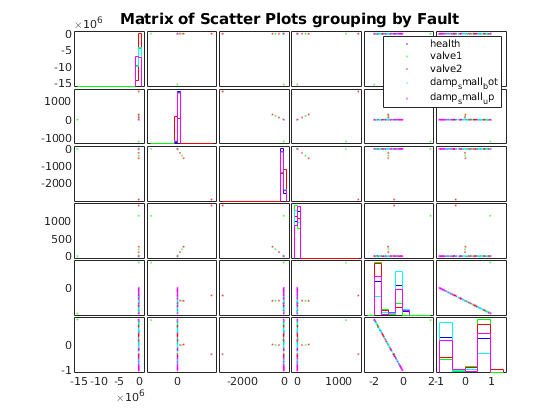

T = feature_table(:, ["f1" "f2" "f3" "f4" "f6" "f7"]);
P = T.Variables;
R = feature_table.Label;
I = strcmp(R, 'health') | strcmp(R, 'valve1') | strcmp(R, 'valve2') | strcmp(R, 'damp_small_bot') |strcmp(R, 'damp_small_up');
f = figure;
gplotmatrix(P(I,:), [], R(I))
title("Matrix of Scatter Plots grouping by Fault")

### Conclusion

Extracted features have no statistical addiction. There is no option to predict fault type, and the best-achieved result was approx 40% accuracy.

## Residual estimation using Simulation Model

### Import datastore and simulation model

addpath("../models/")
run("params.m");

fault_code = "1100001"

Healthy system behavior 


disp('[INFO] Parameters were loaded');

[INFO] Parameters were loaded


datastore = import_dataensemble("../data/data11/*.mat");
clear path2data ext_files
savepath = "../data/data_residual/";
member = read(datastore);
u1 = member.outValveHP{1,1};
u2 = member.outValveWP{1,1};
t = seconds(u1.Time);
u1 = u1.Data;
u2 = u2.Data;


### Reference result from Simulation Model

simOut = sim("../models/model_equation_simply_valves.slx");

position_ref = sim_signal_extract(get(simOut.logsout, "LeverPosition").Values);
velocity_ref = sim_signal_extract(get(simOut.logsout, "LeverVelocity").Values);
flow_ex_ref  = sim_signal_extract(get(simOut.logsout, "FlowExtrusion").Values);
flow_con_ref = sim_signal_extract(get(simOut.logsout, "FlowContraction").Values);

reference.position = position_ref;
reference.velocity = velocity_ref;
reference.flow_ex = flow_ex_ref;
reference.flow_con = flow_con_ref;     


### Example calculation for one member from dataset

[label, r_pos_tt, r_vel_tt, r_fe_tt, r_fc_tt] = generate_residuals(reference, member, t);
data = table({label}, {r_pos_tt}, {r_vel_tt}, {r_fe_tt}, {r_fc_tt}, 'VariableNames', ["Label", "LeverPosition_res", "LeverVelocity_res", "FlowExtrusion_res", "FlowContraction_res"])

data = 1×5 table
       Label         LeverPosition_res      LeverVelocity_res      FlowExtrusion_res     FlowContraction_res
    ____________    ___________________    ___________________    ___________________    ___________________

    {["health"]}    {10000×1 timetable}    {10000×1 timetable}    {10000×1 timetable}    {10000×1 timetable}


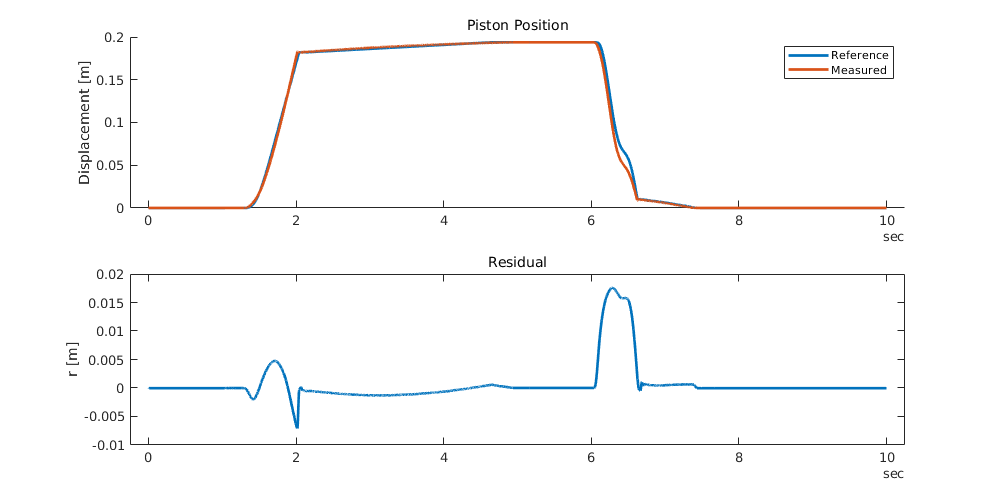

f= figure;
f.Position(3:4) = [1000 500];
grid on
subplot(2,1,1)
pos = member.LeverPosition{1,1};
hold on
plot(pos.Time, position_ref, 'LineWidth', 2)
plot(pos.Time, pos.Data, 'LineWidth', 2)
subtitle("Piston Position")
ylabel("Displacement [m]")
legend("Reference", "Measured")
hold off
subplot(2,1,2)
plot(pos.Time, r_pos_tt.Data, 'LineWidth', 2)
ylabel("r [m]")
subtitle("Residual")

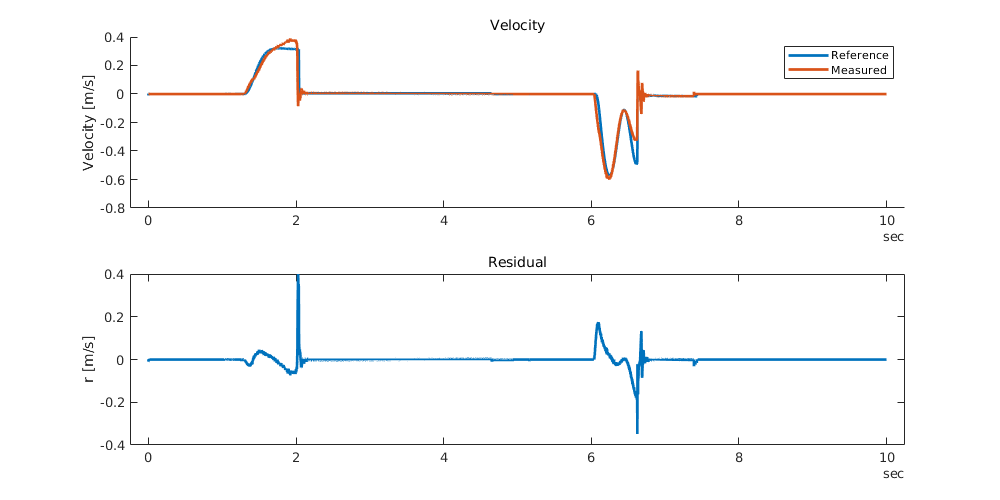

vel = pos; vel.Data = [diff(pos.Data)/Ts; 0];
f= figure;
f.Position(3:4) = [1000 500];
grid on
subplot(2,1,1)
hold on
plot(vel.Time, velocity_ref, 'LineWidth', 2)
plot(vel.Time, vel.Data, 'LineWidth', 2)
subtitle("Velocity")
ylabel("Velocity [m/s]")
legend("Reference", "Measured")
hold off
subplot(2,1,2)
plot(vel.Time, r_vel_tt.Data, 'LineWidth', 2)
ylabel("r [m/s]")
subtitle("Residual")

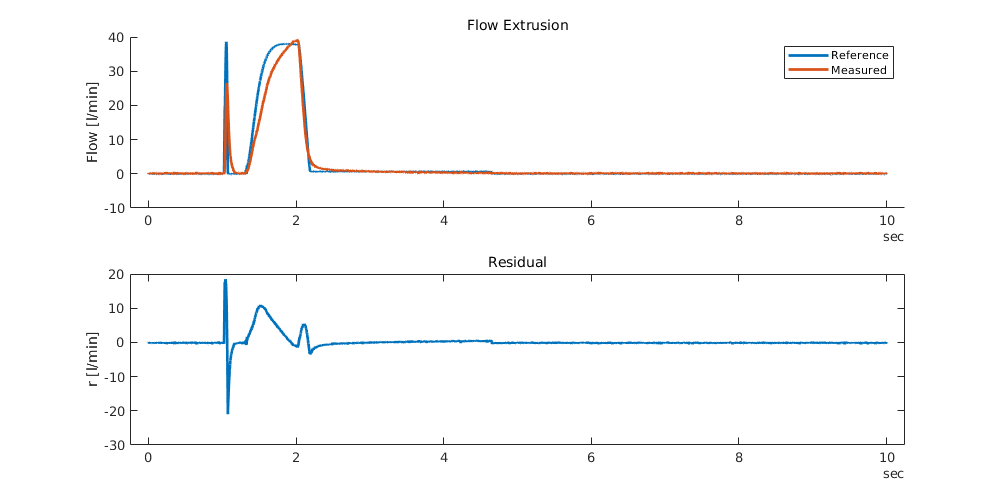

flow_ex = member.FlowExtrusion{1,1};
f= figure;
f.Position(3:4) = [1000 500];
grid on

subplot(2,1,1)
hold on
plot(flow_ex.Time, flow_ex_ref, 'LineWidth', 2)
plot(flow_ex.Time, flow_ex.Data, 'LineWidth', 2)
subtitle("Flow Extrusion")
ylabel("Flow [l/min]")
legend("Reference", "Measured")
hold off
subplot(2,1,2)
plot(flow_ex.Time, r_fe_tt.Data, 'LineWidth', 2)
ylabel("r [l/min]")
subtitle("Residual")

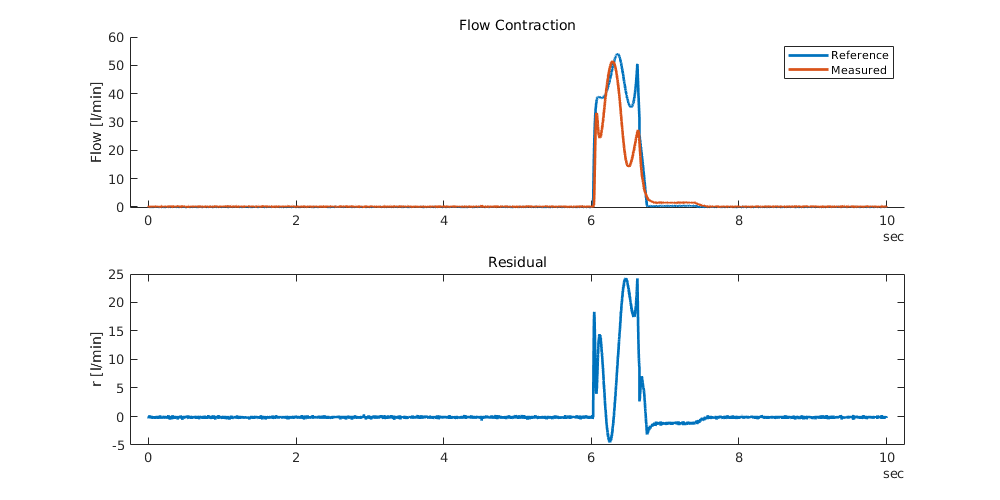

flow_con = member.FlowContraction{1,1};
f= figure;
f.Position(3:4) = [1000 500];
grid on
subplot(2,1,1)
hold on
plot(flow_con.Time, flow_con_ref, 'LineWidth', 2)
plot(flow_con.Time, flow_con.Data, 'LineWidth', 2)
subtitle("Flow Contraction")
ylabel("Flow [l/min]")
legend("Reference", "Measured")
hold off
subplot(2,1,2)
plot(flow_con.Time, r_fc_tt.Data, 'LineWidth', 2)
ylabel("r [l/min]")
subtitle("Residual")

### Calculate whole dataset

calculate_datastore = 0;
if calculate_datastore
reset(datastore)
i = 0;
while hasdata(datastore)
    member = read(datastore);
    [label, r_pos_tt, r_vel_tt, r_fe_tt, r_fc_tt] = generate_residuals(reference, member, t);
    data = table({label}, {r_pos_tt}, {r_vel_tt}, {r_fe_tt}, {r_fc_tt}, 'VariableNames', {'Label', 'LeverPosition_res', 'LeverVelocity_res', 'FlowExtrusion_res', 'FlowContraction_res'});
    save_data(savepath, data, i)
    disp(string(progress(datastore)*100) + "% Done");
    i = i + 1;
end
end

### Import new datastore with residual signals

clear all;
addpath("../utils/")
addpath("featuretables/"); addpath("functions/");
path2data = fullfile("../data/data_residual/*.mat"); ext_files = ".mat";
res_datastore = fileEnsembleDatastore(path2data,ext_files);
res_datastore.ReadFcn = @readData;
res_datastore.WriteToMemberFcn = @writeData;
res_datastore.DataVariables = ["LeverPosition_res"; ...
                            "LeverVelocity_res"; ...
                            "FlowExtrusion_res"; ...
                            "FlowContraction_res"; ...
                            ];
res_datastore.ConditionVariables = ["Label"];
res_datastore.SelectedVariables = ["Label"; ...
                                "LeverPosition_res"; ...
                                "LeverVelocity_res"; ...
                                "FlowExtrusion_res"; ...
                                "FlowContraction_res"];
clear path2data ext_files
% res_datastore = fix_label(res_datastore)

### Import calculated featuretable

residual_featuretable = load("residual_featuretable.mat").residual_featuretable

residual_featuretable = 660×53 table
     Label      LeverPosition_res_stats/ClearanceFactor    LeverPosition_res_stats/CrestFactor    LeverPosition_res_stats/ImpulseFactor    LeverPosition_res_stats/Kurtosis    LeverPosition_res_stats/Mean    LeverPosition_res_stats/PeakValue    LeverPosition_res_stats/RMS    LeverPosition_res_stats/SINAD    LeverPosition_res_stats/SNR    LeverPosition_res_stats/ShapeFactor    LeverPosition_res_stats/Skewness    LeverPosition_res_stats/Std    LeverPosition_res_stats/THD    LeverVelocity_res_stats/ClearanceFactor    LeverVelocity_res_stats/CrestFactor    LeverVelocity_res_stats/ImpulseFactor    LeverVelocity_res_stats/Kurtosis    LeverVelocity_

Reduce features 

pos = regexp(residual_featuretable.Properties.VariableNames, 'LeverPosition_res_stats\/[a-zA-z]*');
var = ~cellfun('isempty', pos);
LeverPosition_res_features = residual_featuretable(:,["Label" residual_featuretable.Properties.VariableNames(var)])

LeverPosition_res_features = 660×14 table
     Label      LeverPosition_res_stats/ClearanceFactor    LeverPosition_res_stats/CrestFactor    LeverPosition_res_stats/ImpulseFactor    LeverPosition_res_stats/Kurtosis    LeverPosition_res_stats/Mean    LeverPosition_res_stats/PeakValue    LeverPosition_res_stats/RMS    LeverPosition_res_stats/SINAD    LeverPosition_res_stats/SNR    LeverPosition_res_stats/ShapeFactor    LeverPosition_res_stats/Skewness    LeverPosition_res_stats/Std    LeverPosition_res_stats/THD
    ________    _______________________________________    ___________________________________    _____________________________________    ________________________________

[~, ranking, ~] =  rank_LeverPosition_features(LeverPosition_res_features)

ranking = 13×2 table
                    Features                     Kruskal-Wallis
    _________________________________________    ______________

    "LeverPosition_res_stats/RMS"                    543.82    
    "LeverPosition_res_stats/PeakValue"              271.95    
    "LeverPosition_res_stats/Std"                    222.89    
    "LeverPosition_res_stats/THD"                    215.35    
    "LeverPosition_res_stats/Kurtosis"               129.67    
    "LeverPosition_res_stats/Skewness"               108.79    
    "LeverPosition_res_stats/SINAD"                  92.685    
    "LeverPosition_res_stats/ShapeFactor"            89.749    
    "LeverPosition_res_stats/Mean"                   73.766    
    "LeverPosition_res_stats/ClearanceFactor"        63.833    
    "LeverPosition_res_stats/ImpulseFactor"          56.891    
    "LeverPosition_res_stats/SNR"                    52.374    
    "LeverPosi

first_five_features = ranking.Features(1:5);
reduced_features_with_label = [first_five_features;"Label"];
dataset = LeverPosition_res_features(:, reduced_features_with_label);
[train_data, test_data] = split_dataset(dataset);



### Fit classification model

Accuracy is 99.49 % 


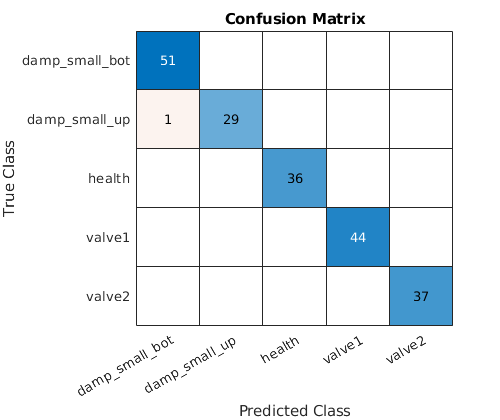

[residual_model, ~ ] = train_model(train_data);

residual_accuracy = confusion_matrix_plot_handler(residual_model, test_data);

## Sensor fault

This section demonstrates sensor fault data generation using a simulation model as a digital twin. 

clc; clear all; close all;
addpath("featuretables/"); addpath("functions/");
addpath("../utils/")
addpath("../models/")

output_path = '../data/data_sensor_fault';
model = 'model_equation_simply_valves';

### Generation fault data

generate_data = 0;

if generate_data
    run("params.m");
    load_system(model);
    open_system(model);
    runParallel = 1;
    
    
    % Run using Parallel Computing Toolbox
    if runParallel && isempty(gcp('nocreate'))
        parpool([2,6]);
    end
    flow_offset_con_values = [zeros(1,20) 1:1:10];
    flow_noise_var_values = [zeros(1,10) linspace(1e-6,1e-4,10) zeros(1,10)];
    fault_code = [zeros(1,10) linspace(1,1,10) linspace(2,2,10)];
    
    for j = 1:numel(flow_offset_con_values)
        tmp = Simulink.SimulationInput(model);
        tmp = setVariable(tmp, 'flow_offset_con', flow_offset_con_values(j));
        tmp = setVariable(tmp, 'flow_noise_var_con', flow_noise_var_values(j) );
        tmp = setVariable(tmp, 'id', fault_code(j));
        simin(j) = tmp;
    end
    
    if ~exist(fullfile(pwd, output_path), 'dir')
        mkdir(fullfile(pwd, output_path))
    end
    
    [status,e] = generateSimulationEnsemble(simin, ...
        fullfile(pwd, output_path), 'UseParallel', runParallel);
    if status
        disp("[INFO] Data was successfully generated")
    else
        warning("Fault in data generation")
    end
    clear simin
end


### Import generated data

clear all;
addpath("../utils/")
addpath("featuretables/"); addpath("functions/");
import_ensemble = 0;
if import_ensemble
output_path = '../data/data_sensor_fault';
ensemble = simulationEnsembleDatastore(output_path);
member = read(ensemble)
reset(ensemble)
add_label = 0;
if add_label
ensemble.DataVariables = [ensemble.DataVariables; "Label"];
while hasdata(ensemble)
    data = read(ensemble);
    id = data.ID{1,1}.Data;
switch id
    case 0
        tmp = "health";
    case 1
        tmp = "noise";
    case 2
        tmp = "offset";
end
    writeToLastMemberRead(ensemble, "Label", tmp);
end
end
ensemble.SelectedVariables = ["Label", "FlowContraction"];
reset(ensemble)
ensemble_table = tall(ensemble);
else
sensor_fault_data = load("sensor_fault_data_table.mat").sensor_fault_data;
end

### Explore sensor fault data

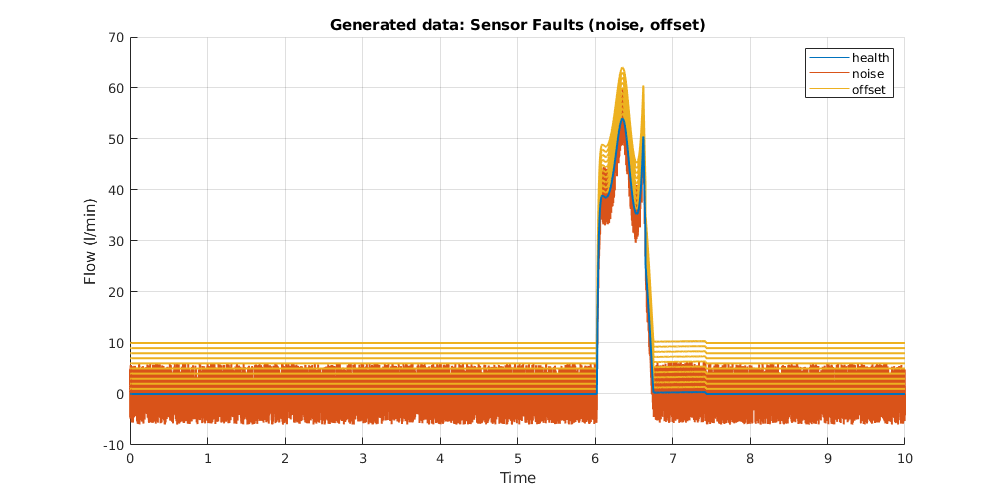

f = figure;
f.Position(3:4) = [1000 500];
ax1 = axes;
hold(ax1, 'on');
L1 = plot(nan, nan, 'Color', '#0072BD');
L2 = plot(nan, nan, 'Color', '#D95319');
L3 = plot(nan, nan, 'Color', '#EDB120');
title("Generated data: Sensor Faults (noise, offset)")
xlabel("Time")
ylabel("Flow (l/min)")
legend(ax1, [L1, L2, L3], {'health', 'noise','offset'}, 'Interpreter', 'none', 'AutoUpdate', 'off')
grid(ax1, 'on')
for i = 1:numel(sensor_fault_data.Label)
    label = sensor_fault_data(i, :).Label;
    data = sensor_fault_data(i, :).FlowContraction{1,1};
    switch label
        case "health"
            plot(ax1, seconds(data.Time), data.Data, 'Color', '#0072BD', 'LineWidth', 1.5)
        case "noise"
            plot(ax1, seconds(data.Time), data.Data, 'Color', '#D95319', 'LineWidth', 1.5)
        case "offset"
            plot(ax1, seconds(data.Time), data.Data, 'Color', '#EDB120', 'LineWidth', 1.5)
    end
    
end

### Calculate and explore features

Features were extracted by using Diagnostic Feature Designer App.

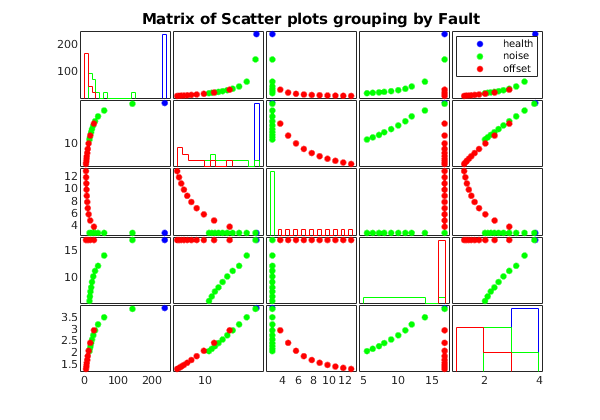

sensor_fault_features = load("sensor_fault_features.mat").sensor_fault_features;

T = sensor_fault_features(:, 2:end);
P = T.Variables;
R = sensor_fault_features.Label;
I = strcmp(R, 'health') | strcmp(R, 'offset') | strcmp(R, 'noise');
f = figure;
f.Position(3) = 600;
gplotmatrix(P(I,:), [], R(I))
title("Matrix of Scatter plots grouping by Fault")

### Fit classification model

Accuracy is 100.00 % 


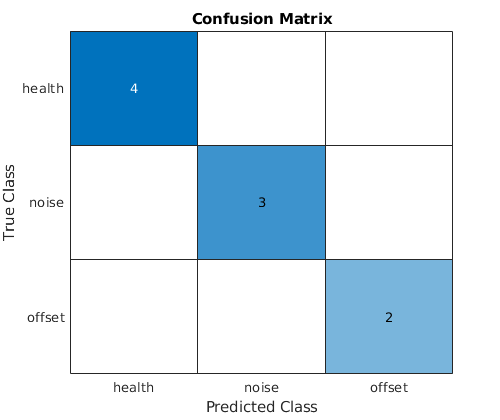

sensor_fault_accuracy = 1

[train_data, test_data] = split_dataset(sensor_fault_features);
[sensor_fault_model, ~] = train_sensor_model(train_data);
sensor_fault_accuracy = confusion_matrix_plot_handler(sensor_fault_model, test_data)

## Functions

function [dataTrain, dataTest] = split_dataset(data)
    cv = cvpartition(size(data,1), 'HoldOut', 0.3);
    idx = cv.test;      
    dataTrain = data(~idx, :);
    dataTest = data(idx, :);
end

function [accuracy] = confusion_matrix_plot_handler(mdl, features)
    required_features = mdl.RequiredVariables;
    targetLabels = features(:,"Label");
    inputTable = features(:, required_features);
    predictedLabels = mdl.predictFcn(inputTable);
    [C,order] = confusionmat(table2array(targetLabels),predictedLabels);
    accuracy = sum(table2array(targetLabels) == predictedLabels)/numel(predictedLabels);
    fprintf("Accuracy is %0.2f %% \n", accuracy*100)
    f = figure;
    f.Position(3) = 500;
    confusionchart(C, order)
    title("Confusion Matrix")
end

function ensemble = add_lable(ensemble)
% Append data
ensemble.DataVariables = [ensemble.DataVariables; "Label"];
% writeToLastMemberRead(ensemble, 'NewVariable', data);

reset(ensemble);
while hasdata(ensemble)
    data = read(ensemble);
    cycle = data.Cycle{1,1}.Data;
    writeToLastMemberRead(ensemble, "Label", cycle);
end
end

function ensemble = fix_label(ensemble)
reset(ensemble);
while hasdata(ensemble)
    data = read(ensemble);
    lab = data.Label{1,1};
    writeToLastMemberRead(ensemble, "Label", lab);
end
end


function signal = sim_signal_extract(signal)
    name = signal.Name;
    signal = ts2timetable(signal).(string(name))(1:end-1);
end

function [] = save_data(path, data, i)
    filename = path + "data_" + string(i) + ".mat";
    save(filename, "data")
end

function [label, r_pos_tt, r_vel_tt, r_fe_tt, r_fc_tt] = generate_residuals(reference, member, t)
    Ts = 1e-3;
    label = string(member.Label{1,1});
    position = member.LeverPosition{1,1};
    velocity = position; velocity.Data = [diff(position.Data)/Ts; 0];
    flow_ex = member.FlowExtrusion{1,1};
    flow_con = member.FlowContraction{1,1};
    
    r_pos = reference.position-position.Data;
    r_vel = reference.velocity-velocity.Data;
    r_fe = reference.flow_ex-flow_ex.Data;
    r_fc = reference.flow_con-flow_con.Data;
    
    r_pos_tt = timetable(r_pos, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
    r_vel_tt = timetable(r_vel, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
    r_fe_tt = timetable(r_fe, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
    r_fc_tt = timetable(r_fc, 'RowTimes', seconds(t), 'VariableNames', {'Data'});
end